# Modèle de barre anti-roulis V2.0

## Introduction

Ce modèle a pour but de dimensionner d'un point de vue dynamique les barres anti-roulis du véhicule Optimus. 

L'implantation de barres anti-roulis a deux objectifs :

- un meilleur comportement dynamique du véhicule en virage. On contrôle les transferts de charge pour contrôler les efforts latéraux encaissables par les roues. La raideur anti-roulis est déterminée de manière à ce que les trains avant et arrière perdent l'adhérence en même temps. C'est ça qui permet de maximiser l'adhérence en virage. 

- moins de prise de roulis

## Calcul des raideurs avant et arrière optimales

### 1) Du point de vue de l'adhérence

Pour maximiser l'adhérence, on veut que les deux trains perdent l'adhérence pour une même valeur d'accélération latérale. 

La fonction force_lat (définie à la fin du script) permet de calculer l'adhérence des deux trains en fonction des paramètres du véhicule. Les entrées sont les raideurs additionnelles à l'avant et à l'arrière, et l'accélération. 

Pour déterminer nos raideurs, on trace l'effort demandé (m*a) et l'effort latéral disponible (adhérence) pour chaque train en fonction de l'accélération latérale. Le train décroche quand l'effort demandé devient supérieur à l'effort disponible. 

W=223+60;
Kav=256; %raideur anti-roulis avant
Kar=125; % " arrière
A=[0.8:0.01:1.4];
n=length(A);
Fr_req=0.52*9.81*W*A;
Ff_req=0.48*9.81*W*A;
F=force_lat(Kav,Kar,A);

tF = 1254

tR = 1180

MR = 1.1000

ans = 3.3757e+05

ans = 3.8124e+05

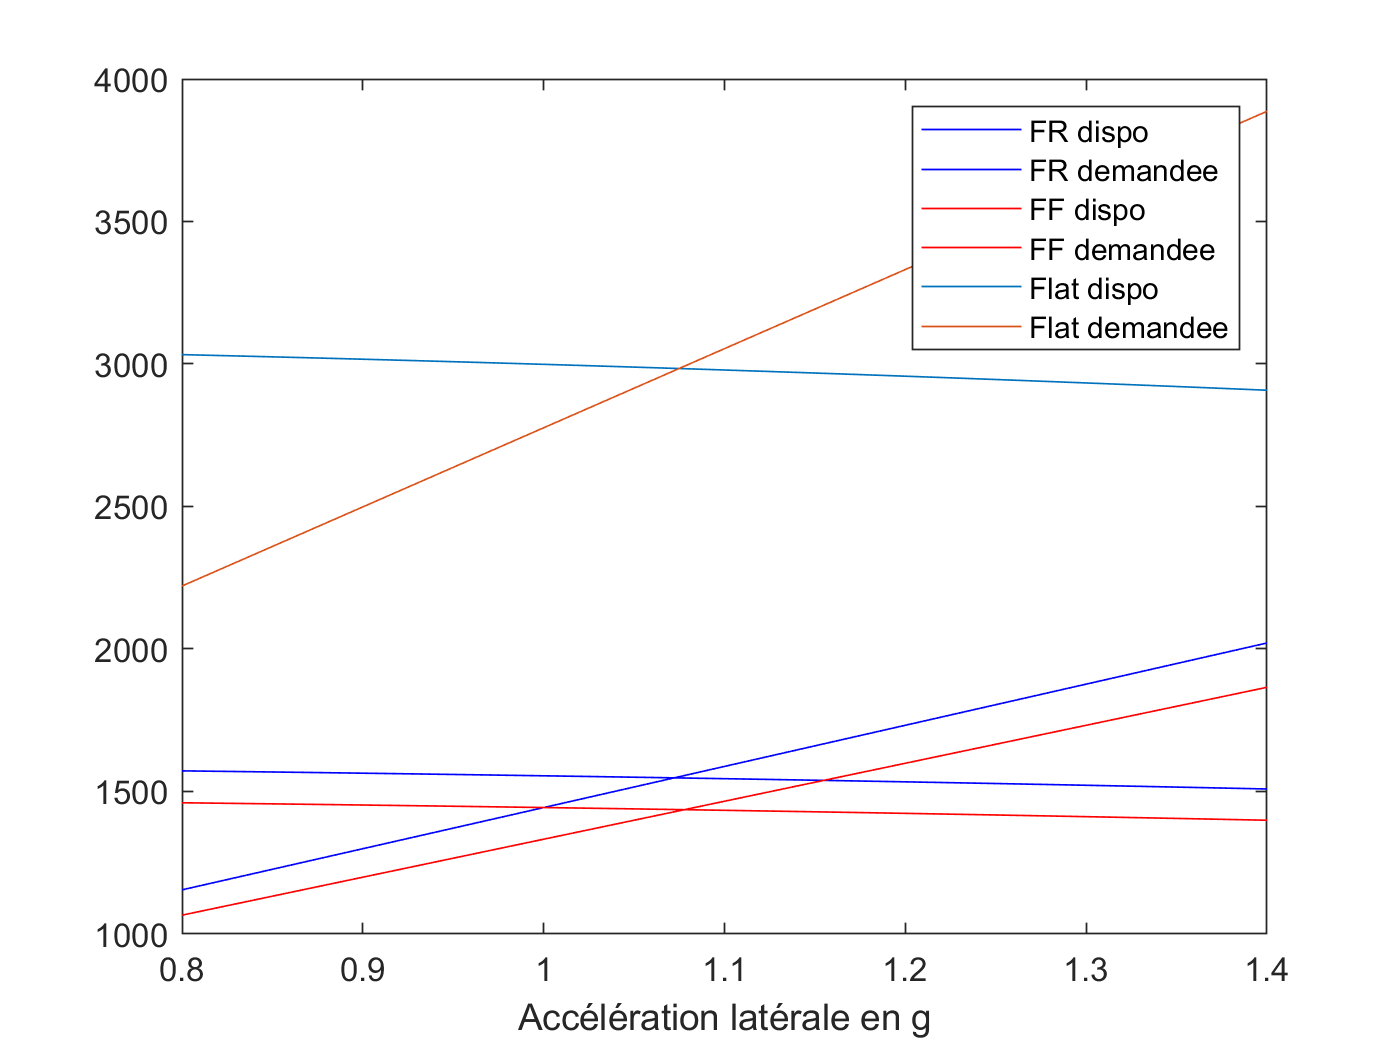

FR=F(1:n); %Force latérale sur le train arrière
FF=F(n+1:2*n); %Force latérale sur le train avant
plot(A,FR,'b',A,Fr_req,'b-',A,FF,'r',A,Ff_req,'r-',A,FR+FF,A,Fr_req+Ff_req)
xlabel('Accélération latérale en g')
legend('FR dispo','FR demandee','FF dispo','FF demandee','Flat dispo','Flat demandee')

L'accélération maximale admissible est de l'ordre de 1,1g.

### 2) Résistance au roulis

Le roll gradient donne l'angle de roulis en degrés par g d'accélération latérale.

Le roll gradient est donné par la formule suivante :

W=223+60;
tF=1.295;
tR=1.220;
t=(tR+tF)/2;
KwR=225*0.175*10^3;

KwR = 39375

KwF=225*0.175*10^3;
KT=190000;% Tire rate N/m
MR=1.1 % Motion ratio
KwR=KwR/MR^2; % rear Wheel rate N/m
KwF=KwF/MR^2; % front wheel rate N/m

MR = 1.1000

KphiR=tR^2*KwR*KT/(114.6*(KwR+KT)); % Roll rate arrière (Nm/° de roulis)
KphiF=tF^2*KwF*KT/(114.6*(KwF+KT)) ;% Roll rate avant (Nm/° de roulis)
MR_F=0.58; % Motion ratio de la barre avant
MR_R=0.4; % Motion ratio de la barre arrière
Kav=Kav/MR_F^2; % Roll rate de l'arb avant (Nm/° de roulis)
Kar=Kar/MR_R^2;% Roll rate de l'arb arrière (Nm/° de roulis)
H=0.300;
% Roll gradient :
%grad=W*H*(KT*t^2/2+180*(Kav+Kar)/pi+(KphiR+KphiF)*t^2/2)/(t^2*KT*(Kav+Kar)/2+pi*t^4*KT*(KphiF+KphiR)/(4*180))

On veut un roll gradient de 1.4°/g. On peut calculer le roll rate total des barres anti-roulis :

Kphides=W*9.81*H/1.4;
KphiA=(pi/180)*(Kphides*KT*t^2/2)/(KT*pi*t^2/360-Kphides)-pi*KwR*t^2/360 % en Nm/°

KphiA = 320.4523

KphiFA=KphiA*MR_F^2/0.053^2*0.48

KphiFA = 1.8421e+04

KphiRA=KphiA*MR_R^2/0.146^2*0.52

KphiRA = 1.2508e+03

## Dimensionnement de la barre 

Pour prendre un roll gradient de 1.4°/g, il faut des raideurs de 100N/mm à l'avant et 88 à l'arrière. En dimensionnant la barre, on prend 105 et 97 (pour des dimensions plus simples) au millieu des réglages. Cela donne un roll gradient de 1.4 °/g. Le code suivant donne la raideur de la barre en fonction des dimensions de la barre et du couteau.

G=81000*10^6; %module de cisaillement en Pa
D=0.015; %diamètre extérieur barre en m
d=0.012; %diamètre intérieur barre en m
L=0.488/2; %demi longueur de la barre en m
A=0.13; % longueur du bras de levier en m
K_bar=pi*G*(D^4-d^4)/(32*L*A^2 )

K_bar = 5.7639e+04

E=210*10^9; % module d'Young en Pa
h=2*D; % largeur du couteau
b=0.05; % épaisseur du couteau
K_arm=E*h*b^3/(4*A^3)

K_arm = 8.9611e+07

K_arb=K_bar*K_arm/(K_bar+K_arm)

K_arb = 5.7602e+04

Pour la raideur maximale, la longueur du bras vaut 70mm, ce qui donne une raideur de 215 N/mm à l'avant et de 198 N/MM à l'arrière. Cela donne une voiture légèrement survireuse et un roll gradient de 0.8 °/g.

Pour la raideur minimale, la longueur du bras vaut 130mm, ce qui donne une raideur de 62 N/mm à l'avant et de 58 N/mm à l'arrière. Cela donne une voiture légèrement survireuse et un roll gradient de 2 °/g.

## Calcul de la masse de la barre à partir des dimensions

Dimensions des couteaux : 99mm, 84, 69, 54. 

La barre est un tube d'acier. Pour la barre avant : 

rho=7800; %masse volumique acier de base
l=0.488;% Longueur de la barre
Df=0.015; % Diamètre extérieur
df=0.013; % Diamètre intérieur
volf=pi*l*((Df/2)^2-(df/2)^2); % Volume de la barre
m_barf=rho*volf % masse de la barre

m_barf = 0.1674

Pour la barre arrière :

l=0.488;
Dr=0.017;
dr=0.0125;
volr=pi*l*((Dr/2)^2-(dr/2)^2);
m_barr=rho*volr

m_barr = 0.3969

Pour les 8 couteaux :

Pour le moment, on considère des couteaux en acier. Il y a 8 couteaux car 2 par côté de chaque barre.

Am=0.15; % Longueur du couteau
h=0.03; % Largeur
b=0.005; % Epaisseur
m_c=8*Am*h*b*rho % masse des 8 couteaux

m_c = 1.4040

Masse totale du système anti-roulis (sans les bielettes et les chappes)

m_ar=m_barf+m_barr+m_c

m_ar = 1.9683

## Fonctions pour les calculs

La première fonction donne le coefficient d'adhérence en fonction de la charge. Cette formule est empirique mais influence minime sur les valeurs de raideur trouvées.

function [t]=tau(FZ)
t=1.2-0.000000022*FZ.^2-0.9*0.00012*FZ;
end

La deuxième fonction permet de calculer les efforts latéraux sur chaque train. Le calcul est basé sur les formules de race cars vehicle dynamics, qui permettent de calculer les transferts de charges latéraux. Une fois qu'on a les charges de chacun des pneus on utilise la fonction tau pour calculer les efforts sur chaque rour puis on somme roue gauche + droite.

function [F]=force_lat(Kav,Kar,A)
% Données
W=223+60; % Poids de la voiture+chauffeur
l=1575; % Empattement
tF=1254%1295; % Voie
tR=1180%1220;
KwR=225*0.175; % Raideur de suspension arrière
KwF=225*0.175; % Raideur de suspension avant
MR=1.1 % Motion ratio
KwR=KwR/MR^2; % rear Wheel rate
KwF=KwF/MR^2; % front wheel rate
KT=190; % Raideur pneu
KphiR=tR^2*KwR*KT/(114.6*(KwR+KT)); % Roll rate arrière (Nm/° de roulis)
KphiF=tF^2*KwF*KT/(114.6*(KwF+KT)) ;% Roll rate avant (Nm/° de roulis)
MR_F=5; % Motion ratio de la barre avant
MR_R=12; % Motion ratio de la barre arrière
Kav=Kav/MR_F^2; % Roll rate de l'arb avant (Nm/° de roulis)
Kar=Kar/MR_R^2;% Roll rate de l'arb arrière (Nm/° de roulis)
KphiR+Kar % Roll rate total arrière (Nm/° de roulis)
KphiF+Kav % Roll rate total avant (Nm/° de roulis)
WF=0.48*W; % Masse à l'avant
WR=0.52*W; % Masse à l'arrière
h=(0.42*60+0.310*223)/W; % Hauteur du cdg
H=300; % CDG to roll axis
b=l/(1+WR/WF);
a=l-b;
ZRR=50.67; % Hauteur de centre instantané de roulis arrière
ZRF=36.44; % Hauteur de centre instantané de roulis avant
dWF=A.*(W/tF)*(H*(KphiF+Kav)./(KphiF+Kav+KphiR+Kar)+b*ZRF/l); % Transfert de charge avant
dWR=A.*(W/tR)*(H*(KphiR+Kar)./(KphiF+Kav+KphiR+Kar)+a*ZRR/l); % Transfert de charge arrière
WFO=WF/2+dWF; % Charge sur la roue
WFI=WF/2-dWF;
WRO=WR/2+dWR;
WRI=WR/2-dWR;
RF=9.81*WFO.*tau(9.81*WFO)+9.81*WFI.*tau(9.81*WFI); % Effort latéral sur le train
RR=9.81*WRO.*tau(9.81*WRO)+9.81*WRI.*tau(9.81*WRI);
F=[RR,RF];
end